# Satelliete Attitude Control

Simulate the motion of a satellite controlled with three pairs of reaction wheels

Set dimensions and mass of satellite and wheels:

clear
% Make a rectangular prism:
lx = 1;
ly = 2;
lz = 5;

m_B = 50; % satellite mass
m_w = 2; % reaction wheels' masses 

p.I_x = (1/12)*m_B*(ly^2+lz^2);
p.I_y = (1/12)*m_B*(lz^2+lx^2);
p.I_z = (1/12)*m_B*(lx^2+ly^2);

R = 0.9*lx; % reaction wheel radius
d = 0.25*lx; % reaction wheel depth
p.I_s  =  m_w*R^2;
p.I_px = (m_w/6)*(3*R^2+d^2) + (m_w/2)*(lx+d)^2;
p.I_py = (m_w/6)*(3*R^2+d^2) + (m_w/2)*(ly+d)^2;
p.I_pz = (m_w/6)*(3*R^2+d^2) + (m_w/2)*(lz+d)^2;

Set control gains:

K_p = 0.75;
K_d = 1;
K_i = 0.05;

There's a little complexity hiding here: technically there are at least three different control gains, one for each of the angles we're trying to set; plus more for cross terms (essentially there is a 3x3 gain matrix). But, in the code we just scale each of the controls for each of the angles by the moment of inertia for that axis so that each of the axis is being controlled similarly.

Note: Target orientation is set randomly.

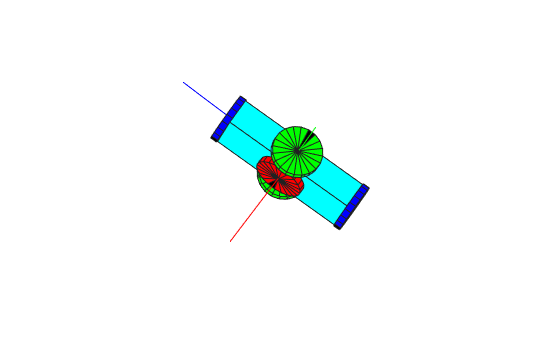

p.Kp = K_p*diag([p.I_x,p.I_y,p.I_z]); % proportional gain matrix
p.Kd = K_d*diag([p.I_x,p.I_y,p.I_z]); % derivative gain matrix
p.Ki = K_i*diag([p.I_x,p.I_y,p.I_z]); % integral gain matrix

theta0 = [0;0;0]; %initial orientation
p.c = (pi/3)*rand(3,1); %target orientation
omega0 = [0;0;0]; %initial angular speed

tf = 10; %simulation duration

function z_dot = EOM(~,z,p)
% z = [theta_x; theta_y; theta_z; - body euler angles
%      omega_x; omega_y; omega_z; - body angular speeds
%      Omega_x; Omega_y; Omega_z; - reaction wheel angular speeds
%      phi_x; phi_y; phi_z        - reaction wheel angles
%      q_x; q_y; q_z;             - integrated error
theta_dot = [(z(4)*cos(z(3)) - z(5)*sin(z(3)))*sec(z(2));
              z(4)*sin(z(3)) + z(5)*cos(z(3));
            -(z(4)*cos(z(3)) - z(5)*sin(z(3)))*tan(z(2)) + z(6)]; % change in euler angles

q_dot = p.c - z(1:3); % change in integrated error

P = p.Kp*(p.c - z(1:3)); % proportional control
D = p.Kd*-theta_dot;    % derivative control
I = p.Ki*z(13:15);         % integral control

Omega_dot = -(P+D+I)/p.I_s; % change in reaction wheels' angular speeds
phi_dot = z(7:9); % change in reaction wheel angles;

%change in body's angular speeds
omega_dot(1) = (p.I_s*(-Omega_dot(1)+z(8)*z(6)-z(9)*z(5)) + (p.I_pz-p.I_py + p.I_y-p.I_z)*z(5)*z(6))/((p.I_py+p.I_pz+p.I_s)+p.I_x);
omega_dot(2) = (p.I_s*(-Omega_dot(2)+z(9)*z(4)-z(7)*z(6)) + (p.I_px-p.I_pz + p.I_z-p.I_x)*z(6)*z(4))/((p.I_pz+p.I_px+p.I_s)+p.I_y);
omega_dot(3) = (p.I_s*(-Omega_dot(3)+z(7)*z(5)-z(8)*z(4)) + (p.I_py-p.I_px + p.I_x-p.I_y)*z(4)*z(5))/((p.I_px+p.I_py+p.I_s)+p.I_z);

z_dot = [theta_dot;omega_dot';Omega_dot;phi_dot;q_dot];
end

[t,z] = ode45(@(t,z) EOM(t,z,p),linspace(0,tf,40*tf),[theta0;omega0;zeros(9,1)]);
z = z';

% animate:
close all
figure(1)
% Create body
prism = plotPrism(lx,ly,lz,[0,1,1],1);
% draw target position
final = hgtransform;
plot3([0,lz],[0,0],[0,0],'r','Parent',final)
plot3([0,0],[0,lz],[0,0],'g','Parent',final)
plot3([0,0],[0,0],[0,lz],'b','Parent',final)
set(final,'Matrix',[spinmat([1,2,3],p.c'),[0;0;0];[0,0,0,1]])
% Create reaction wheels:
[a,b,c] = cylinder;
a=R*a; b=R*b; c=c*d;
colrx = cat(3,1,0,0).*ones(size(a)); colrx(1,1,:)=cat(3,0,0,0);
colry = cat(3,0,1,0).*ones(size(a)); colry(1,1,:)=cat(3,0,0,0);
colrz = cat(3,0,0,1).*ones(size(a)); colrz(1,1,:)=cat(3,0,0,0);
X = hgtransform;
surf( c+lx/2,a,b,colrx,'Parent',X)
surf(-c-lx/2,a,b,colrx,'Parent',X)
surf( (lx/2+d)*ones(2,21),[zeros(1,21);a(1,:)],[zeros(1,21);b(1,:)],colrx,'Parent',X)
surf(-(lx/2+d)*ones(2,21),[zeros(1,21);a(1,:)],[zeros(1,21);b(1,:)],colrx,'Parent',X)
Y = hgtransform;
surf(b, c+ly/2,a,colry,'Parent',Y)
surf(b,-c-ly/2,a,colry,'Parent',Y)
surf([zeros(1,21);b(1,:)], (ly/2+d)*ones(2,21),[zeros(1,21);a(1,:)],colry,'Parent',Y)
surf([zeros(1,21);b(1,:)],-(ly/2+d)*ones(2,21),[zeros(1,21);a(1,:)],colry,'Parent',Y)
Z = hgtransform;
surf(a,b, c+lz/2,colrz,'Parent',Z)
surf(a,b,-c-lz/2,colrz,'Parent',Z)
surf([zeros(1,21);a(1,:)],[zeros(1,21);b(1,:)], (lz/2+d)*ones(2,21),colrz,'Parent',Z)
surf([zeros(1,21);a(1,:)],[zeros(1,21);b(1,:)],-(lz/2+d)*ones(2,21),colrz,'Parent',Z)

axis equal off
view([160 40])
xlim([-1,1]*lz*0.6);ylim([-1,1]*lz*0.6);zlim([-1,1]*lz*0.6)

for i=1:length(t)
    mat = spinmat([1,2,3],z([1,2,3],i)');
    set(prism,'Matrix',[mat,[0;0;0];[0,0,0,1]])
    set(X,'Matrix',[mat*spinmat(1,z(10,i)),[0;0;0];[0,0,0,1]])
    set(Y,'Matrix',[mat*spinmat(2,z(11,i)),[0;0;0];[0,0,0,1]])
    set(Z,'Matrix',[mat*spinmat(3,z(12,i)),[0;0;0];[0,0,0,1]])
    drawnow
end

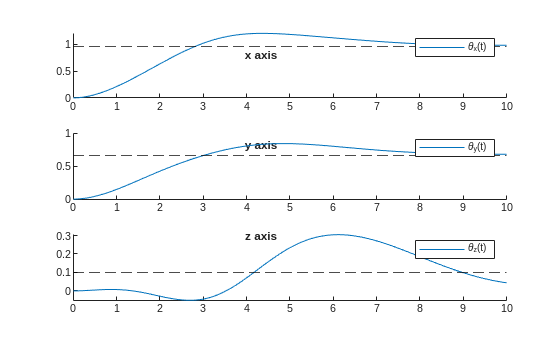

% plot time-histories of euler angles
figure(2)
clf
subplot(3,1,1)
title('x axis')
hold on
plot(t,z(1,:),'DisplayName','\theta_x(t)')
legend('AutoUpdate','off')
yline(p.c(1),'--k')

subplot(3,1,2)
title('y axis')
hold on
plot(t,z(2,:),'DisplayName','\theta_y(t)')
legend('AutoUpdate','off')
yline(p.c(2),'--k')

subplot(3,1,3)
title('z axis')
hold on
plot(t,z(3,:),'DisplayName','\theta_z(t)')
legend('AutoUpdate','off')
yline(p.c(3),'--k')

function h = plotPrism(l1,l2,l3,colr,alpha)
h = hgtransform;
[a,b] = meshgrid([-1,1]/2, [-1,1]/2); c = ones(2)/2;
colr = repmat(reshape(colr,[1,1,3]),[2,2,1]);
surf( a*l1, b*l2, c*l3,colr,'FaceAlpha',alpha,'Parent',h)
surf( a*l1, b*l2,-c*l3,colr,'FaceAlpha',alpha,'Parent',h)
surf( c*l1, a*l2, b*l3,colr,'FaceAlpha',alpha,'Parent',h)
surf(-c*l1, a*l2, b*l3,colr,'FaceAlpha',alpha,'Parent',h)
surf( b*l1, c*l2, a*l3,colr,'FaceAlpha',alpha,'Parent',h)
surf( b*l1,-c*l2, a*l3,colr,'FaceAlpha',alpha,'Parent',h)
end